# MNIST classification: held-out evaluation

This Live Script evaluates saved publication models through the current BANFF architecture. It reports the same task-level statistics and diagnostic plot families as the older task-specific implementation.

clearvars; close all; clc;

## Locate the publication code

evaluation_directory = fileparts(mfilename('fullpath'));
repository_root = fileparts(evaluation_directory);
addpath(repository_root, evaluation_directory);

## Choose the saved experiment family

Use the same profile and scientific overrides that were used for training.

seeds = 1:3;
profile = "main";            % main, full_rank, spsa, or neuron_sweep
overrides = struct();         % e.g. struct('N_hidden',8000) for neuron_sweep

## Choose display and export behaviour

display_options = struct();
display_options.representative_seed_index = 1;
display_options.representative_initial_condition = 1;
display_options.replay_static_spikes = true;
display_options.save_figures = false;
display_options.output_directory = fullfile(repository_root, ...
    'outputs', 'evaluation', 'mnist');

## Run held-out testing, statistics, seed audit, and plots


BANFF held-out test evaluation: mnist (main profile)
Seeds: [1 2 3]

Per-seed held-out test results
    Seed     Loss      AccuracyPercent    CrossEntropy    ActiveNeuronPercent
    ____    _______    _______________    ____________    ___________________

     1       1.0469         82.16            1.0469               100        
     2      0.98124         83.57           0.98124               100        
     3       1.0548         82.02            1.0548               100        

Across-seed mean and sample SD
           Metric             Mean     SampleSD    FiniteN
    _____________________    ______    ________    _______

    "Loss"                   1.0276    0.040371    

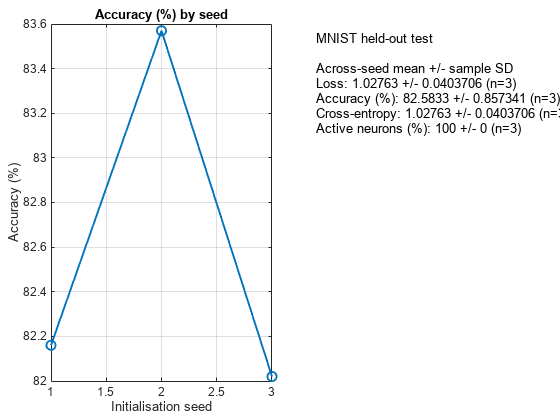

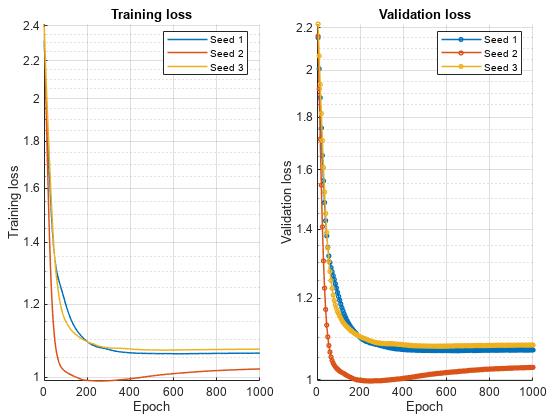

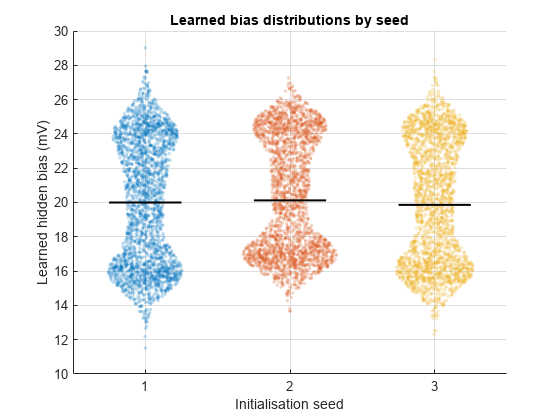

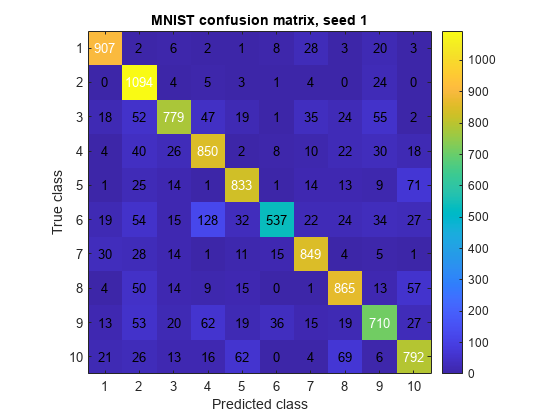

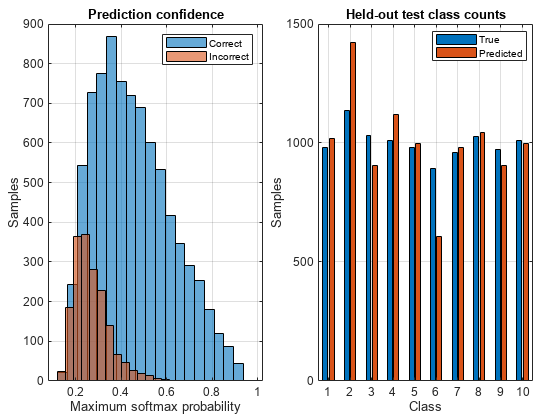

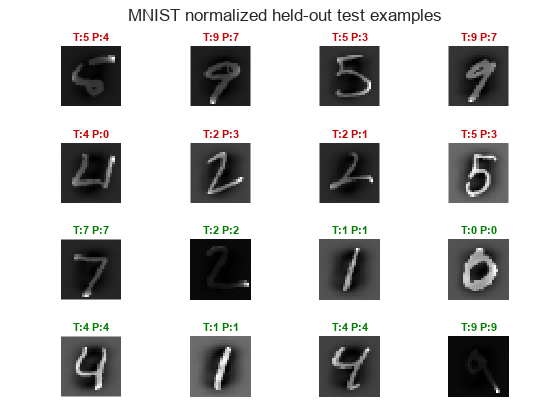

Exact full-held-out test current magnitudes (RMS over neurons, samples and time)
     Condition     EncoderRmsMv    NetRecurrentRmsMv    RecurrentToEncoderRms    GrossEncoderRmsMv    GrossRecurrentRmsMv    NetToGrossRecurrentRms    NetToGrossEncoderRms    AdaptationRmsMv    BiasDeviationRmsMv    DecoderContributionRms
    ___________    ____________    _________________    _____________________    _________________    ___________________    ______________________    ____________________    _______________    __________________    ______________________

    "Untrained"       1.9381            0.52571                0.2

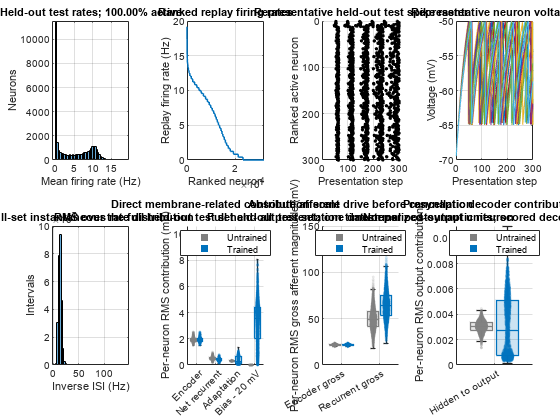

Current comparison: all 10000 held-out test samples and 300 presentation steps (3e+06 observations per neuron and condition).


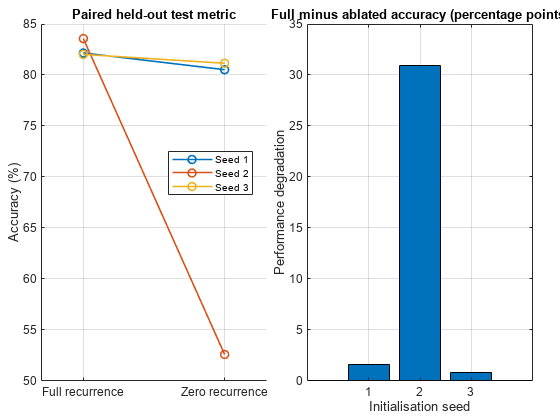

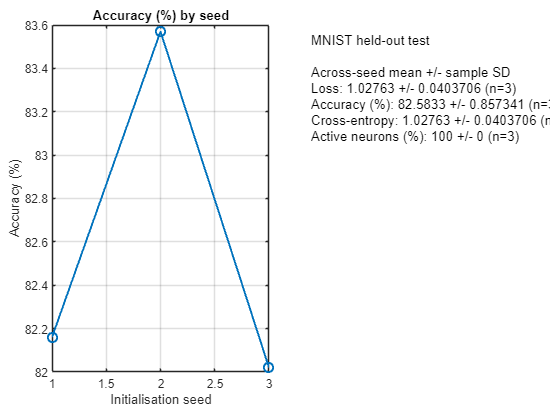

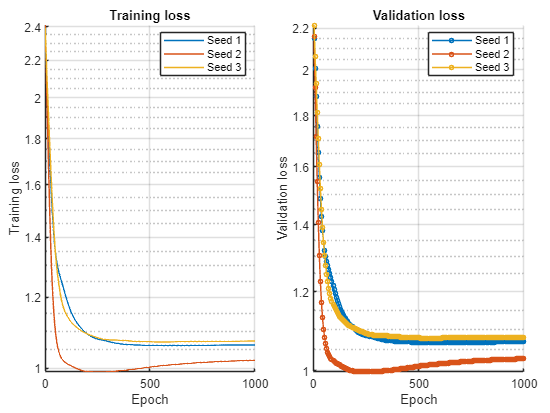

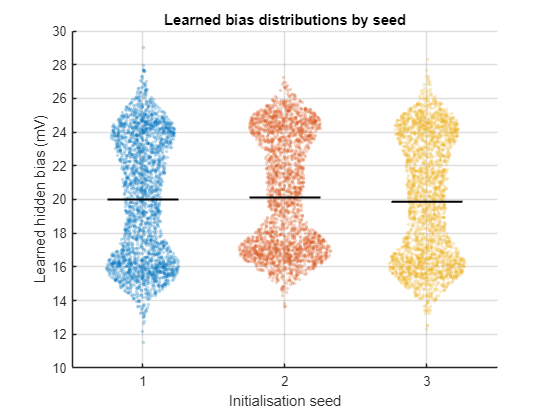

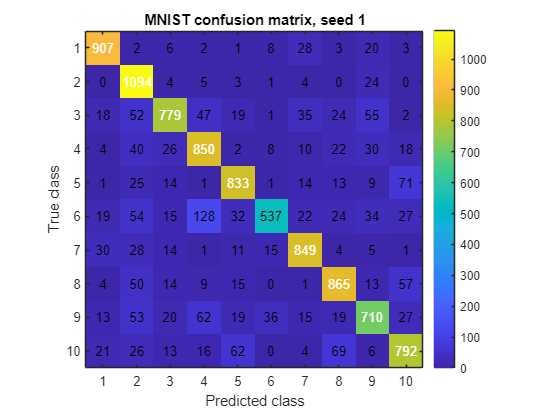

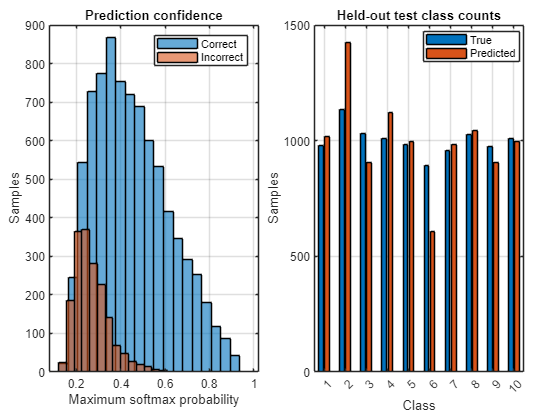

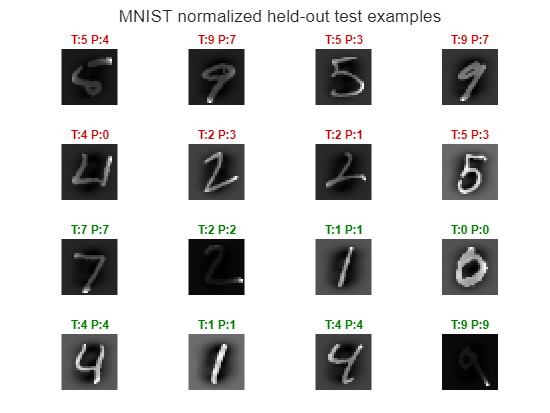

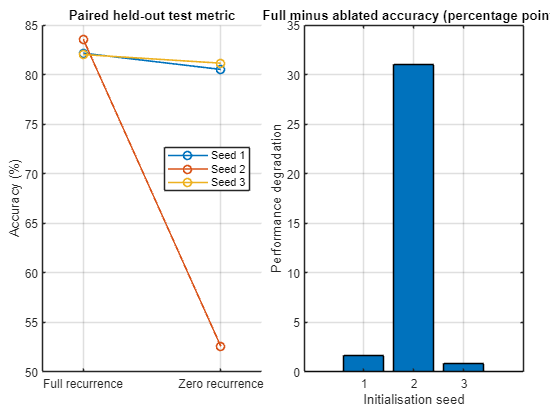

report = banff_evaluate_task("mnist", seeds, profile, overrides, display_options);

## Machine-readable results

report.seed_table

ans = 3×5 table
    Seed     Loss      AccuracyPercent    CrossEntropy    ActiveNeuronPercent
    ____    _______    _______________    ____________    ___________________

     1       1.0469         82.16            1.0469               100        
     2      0.98124         83.57           0.98124               100        
     3       1.0548         82.02            1.0548               100        


report.summary_table

ans = 4×4 table
           Metric             Mean     SampleSD    FiniteN
    _____________________    ______    ________    _______

    "Loss"                   1.0276    0.040371       3   
    "AccuracyPercent"        82.583     0.85734       3   
    "CrossEntropy"           1.0276    0.040371       3   
    "ActiveNeuronPercent"       100           0       3   


report.network_seed_audit

ans = 3×4 table
    Seed                                                             ModelFile                                                                                       CheckpointHash                                                    FixedNetworkProbeHash                       
    ____    ___________________________________________________________________________________________________________________________    __________________________________________________________________    __________________________________________________________________

     1      "/home/kai.mason/Documents/BANFF_SNN_pub/outputs/models/mnist_eprop_low_rank_hard_spike_N32000_cfgb984189154c3_seed001.mat"    "48f6e34a115340bb0fe21db34962c7ba196e7b4cbc7394c4d9973044e5c9d0c5"    "8a03c9aaadeea75965e2aaf6a814128d01ed96aed177397bd05985505402d3f2"
     2      "/home/